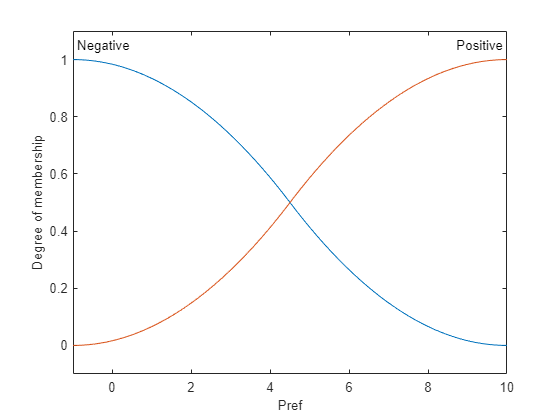

%Neurofeedback Fuzzy inference system
%% Version V1
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier Herrara-Vega
% Date - February 9th, 2022
% Email - madlsh3517@gmail.com

cpFIS = mamfis(...
    'NumInputs', 2, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 4, ...
    'AddRule', 'none');
%Inputs

cpFIS.Inputs(1).Name = 'Pref';
%cpFIS.Inputs(1).Range = [-5, 20]; 
cpFIS.Inputs(1).Range = [-1, 10]; 
cpFIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
%cpFIS.Inputs(1).MembershipFunctions(1).Parameters = [0 20];
cpFIS.Inputs(1).MembershipFunctions(1).Parameters = [-1 10];
cpFIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cpFIS.Inputs(1).MembershipFunctions(2).Type ='smf'; %S-shaped memebersh
cpFIS.Inputs(1).MembershipFunctions(2).Parameters = [-1 10];    
%cpFIS.Inputs(1).MembershipFunctions(2).Parameters = [0 20];

cpFIS.Inputs(2).Name = 'Place';
cpFIS.Inputs(2).Range = [1, 4]; 
cpFIS.Inputs(2).MembershipFunctions(1).Name = 'one';
cpFIS.Inputs(2).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
cpFIS.Inputs(2).MembershipFunctions(1).Parameters = [0 1];
cpFIS.Inputs(2).MembershipFunctions(2).Name = 'two';
cpFIS.Inputs(2).MembershipFunctions(2).Type ='zmf'; %Z-shaped memebership function
cpFIS.Inputs(2).MembershipFunctions(2).Parameters = [1 2];
cpFIS.Inputs(2).MembershipFunctions(3).Name = 'three';
cpFIS.Inputs(2).MembershipFunctions(3).Type ='smf'; %S-shaped memebersh
cpFIS.Inputs(2).MembershipFunctions(3).Parameters = [2 3];
cpFIS.Inputs(2).MembershipFunctions(4).Name = 'four';
cpFIS.Inputs(2).MembershipFunctions(4).Type ='smf'; %S-shaped memebersh
cpFIS.Inputs(2).MembershipFunctions(4).Parameters = [3 4];

plotmf(cpFIS, 'input', 1, 1000);

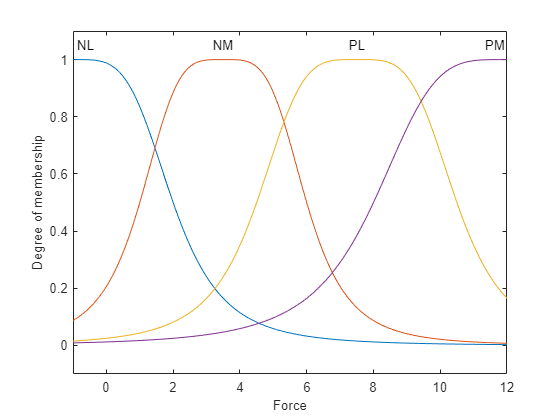

%Outputs

%Basic inference application for control just pressure

cpFIS.Outputs(1).Name = 'Force'; %Salida para controlar presion
cpFIS.Outputs(1).Range = [-1,12]; %Rango de la salida del control
%cpFIS.Outputs(1).Range = [0,10]; %Rango de la salida del control

cpFIS.Outputs(1).MembershipFunctions(1).Name = 'NL'; %Negative Low alternative
cpFIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpFIS.Outputs(1).MembershipFunctions(1).Parameters = [3,2,-1];

cpFIS.Outputs(1).MembershipFunctions(2).Name = 'NM'; %Negative Medium alternative
cpFIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
cpFIS.Outputs(1).MembershipFunctions(2).Parameters = [2.5,2,3.5];

cpFIS.Outputs(1).MembershipFunctions(3).Name = 'PL'; %Positive Low alternative
cpFIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
cpFIS.Outputs(1).MembershipFunctions(3).Parameters = [3,2,7.5];

cpFIS.Outputs(1).MembershipFunctions(4).Name = 'PM'; %Positive Medium alternative
cpFIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
cpFIS.Outputs(1).MembershipFunctions(4).Parameters = [4,2,12];



plotmf(cpFIS, 'output', 1, 1000);

%Cute basic rules
% 
% rules = ["If Pref is Negative and Pobs is Negative then Force is NL";...
%     "If Pref is Positive and Pobs is Negative then Force is NM";...
%     "If Pref is Positive and Pobs is Positive then Force is PL";...
%     "If Pref is Negative and Pobs is Positive then Force is PM"];
% 
% rules = ["If Pref is Negative then Force is NM";...
%     "If Pref is Positive then Force is PM";...
%     "If Setpoint is Positive then Force is PL";...
%     "If Setpoint is Negative then Force is NL"];

% rules = ["If Pref is Negative then Force is NM";...
%     "If Pref is Positive then Force is PL"];

rules = ["If Place is one and Pref is Positive then Force is PM";...
        "If Place is two and Pref is Negative then Force is PL";...
        "If Place is three and Pref is Positive then Force is NL";...
        "If Place is four and Pref is Positive then Force is NM"];

cpFIS = addRule(cpFIS, rules);

